# Sinusoidal Input (Stochastic)

## 2Freq

load('scope2f.mat');
load('tout2f.mat');

Input values

y1=scope.signals(1).values; 

y1=y1.';
x1=tout;
x1=x1.';

figure
plot(x1,y1);
hold on


Response values

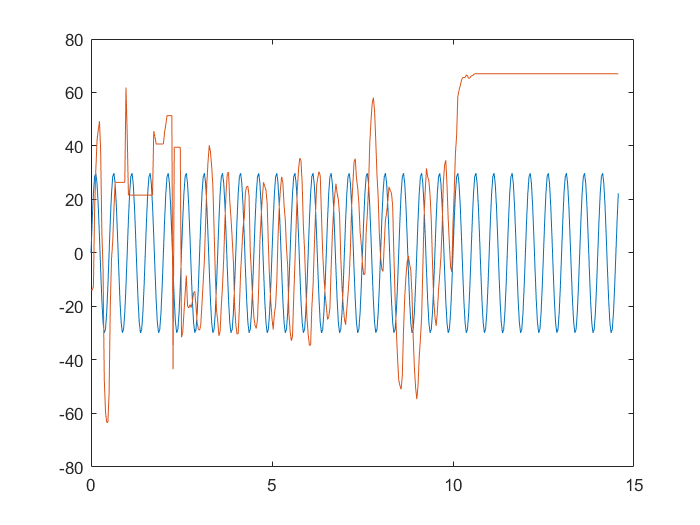

y2=scope.signals(2).values; 

y3=squeeze(y2);
y3=y3.';
constref=80;
y3=y3-constref;

plot(x1,y3);
hold off

Chosing points

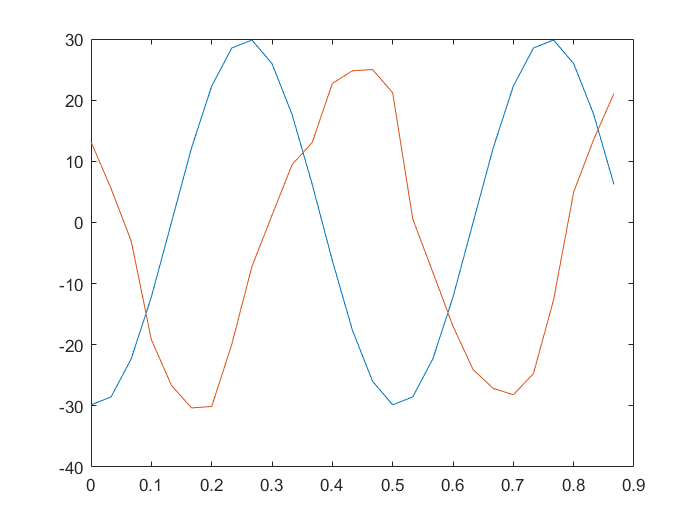

chosen_ref_sto=y1(117:143);
chosen_t_sto=x1(1:27);

plot(chosen_t_sto,chosen_ref_sto);
hold on

chosen_y=y3(117:143);

plot(chosen_t_sto,chosen_y);
hold off

Finding data

Ts=1/30;

[gain_sto, phase_sto, w_sto] = findbodedata2_sto(chosen_ref_sto, chosen_y, Ts, 0)

gain_sto = -1.1317

phase_sto = 248.9971

w_sto =    11.7810   11.7810


Comparing data

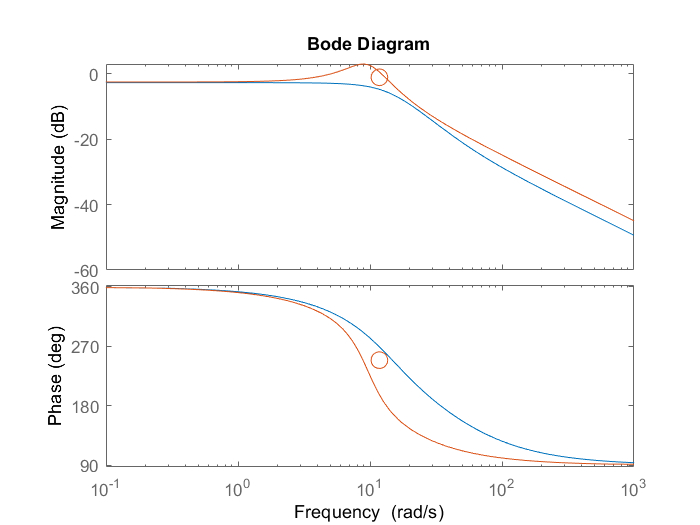

figure
semilogx(w_sto,gain_sto,'o','MarkerSize',10)
hold on

bode(Gs_sto_final)
hold on

semilogx(w_sto,phase_sto,'o','MarkerSize',10)
hold on

bode(Gs_levy_sto)
hold off

## 15Freq

load('scope15f.mat');
load('tout15f.mat');

Input values

y1=scope.signals(1).values; 

y1=y1.';
x1=tout;
x1=x1.';

figure
plot(x1,y1);
hold on


Response values

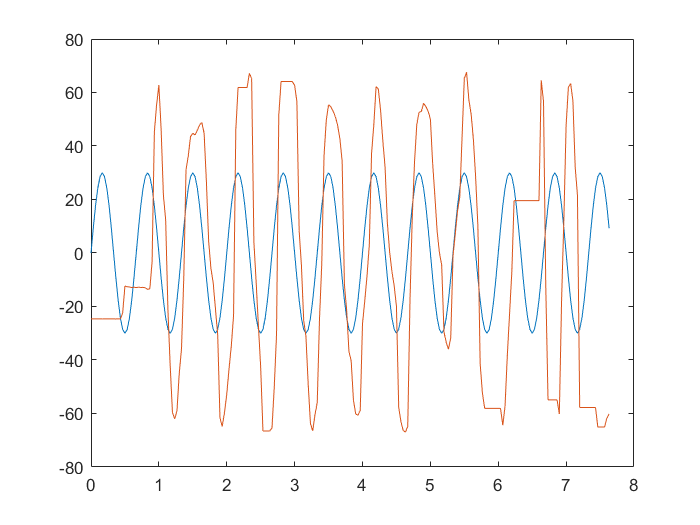

y2=scope.signals(2).values; 

y3=squeeze(y2);
y3=y3.';
constref=80;
y3=y3-constref;

plot(x1,y3);
hold off

Chosing points

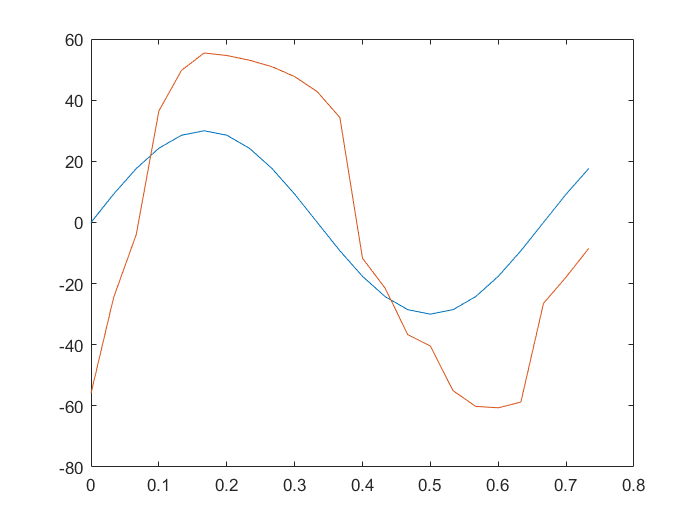

chosen_ref_sto=y1(101:123);
chosen_t_sto=x1(1:23);

plot(chosen_t_sto,chosen_ref_sto);
hold on

chosen_y=y3(101:123);

plot(chosen_t_sto,chosen_y);
hold off

Finding data

Ts=1/30;

[gain_sto, phase_sto, w_sto] = findbodedata2_sto(chosen_ref_sto, chosen_y, Ts, 0)

gain_sto = 6.5790

phase_sto = -35.9580

w_sto =     5.8905    5.8905


Comparing data

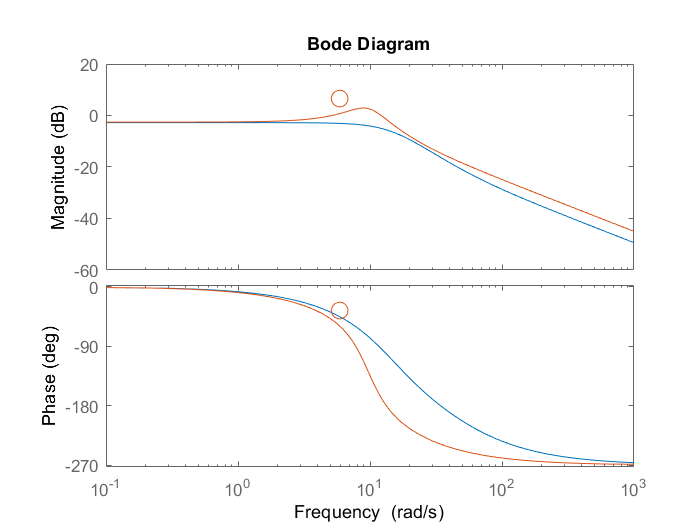

figure
semilogx(w_sto,gain_sto,'o','MarkerSize',10)
hold on

h=bodeplot(Gs_sto_final);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot
hold on


semilogx(w_sto,phase_sto,'o','MarkerSize',10)
hold on

h=bodeplot(Gs_levy_sto);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot  
hold off